assert(endsWith(pwd, "non-ferromagnetic metal plate with hole in time domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

EM.num = 1;
EM.inner_radius = 3.75e-3; % (m)
EM.outer_radius = 6.00e-3; % (m)
EM.length = 4.00e-3; % (m)
EM.Nturns = 60;

EM_pos = [-20e-3, 0, 4e-3]; % (m)
EM = SetPositionRotation3D(EM, EM_pos, [1,0,0], deg2rad(0));
clear EM_pos

#### Sensor

Sensor.num = 1;
Sensor.side_length = 1e-3;

Sensor_pos = [-20e-3, 0, 1.5e-3];
Sensor = SetPositionRotation3D(Sensor, Sensor_pos, [1,0,0], 0);
clear Sensor_pos

#### Model

vertex_file = 'plate_l72_t2_hole_d12_vertex.csv';
element_file = 'plate_l72_t2_hole_d12_element.csv';
Model = BuildModel3D('File', vertex_file, element_file, 1e-3);

build model took 0.09 seconds


clear vertex_file element_file

Model.conductivity = 7.407e5 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, EM);

build governing equation took 29.09 seconds


#### Solve in time domain

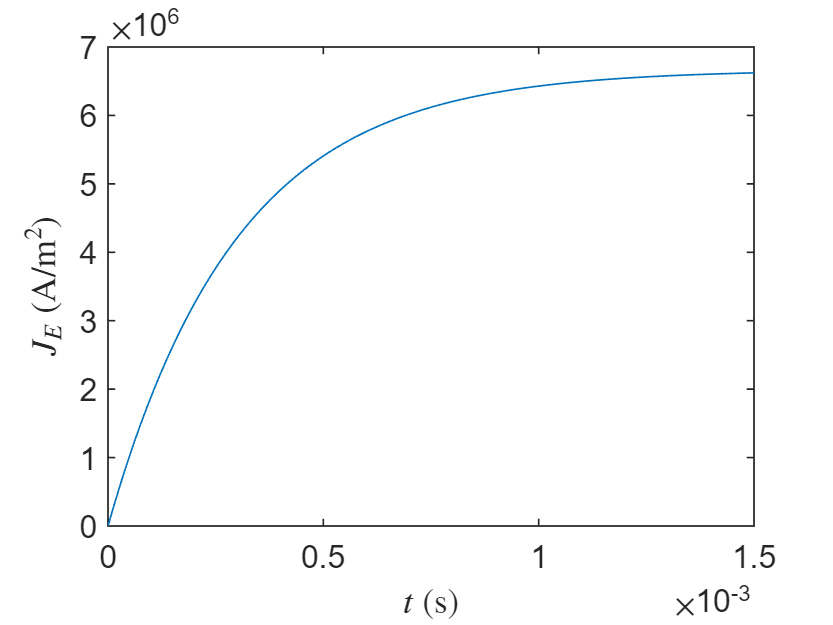

I_E_ss = 1; % (A)
J_E_ss = I_E_ss * EM.Nturns / ((EM.outer_radius-EM.inner_radius)*EM.length); % (A/m^2)
tau = 3e-4; % (s)

EM.time_domain.current_density = @(t) J_E_ss * (1 - exp(-t/tau));
EM.time_domain.current_density_diff = @(t) J_E_ss/tau * exp(-t/tau);
% EM.time_domain.current_density_diff2 = @(t) -J_E_ss/tau^2 * exp(-t/tau);
EM.time_domain.time_span = [0, 1.5e-3]; % (s)

t = linspace(EM.time_domain.time_span(1), EM.time_domain.time_span(end));
plot(t, EM.time_domain.current_density(t))
ylabel('$J_E$ (A/m$^2$)', 'Interpreter','latex')
xlabel('$t$ (s)', 'Interpreter','latex')

clf
clear I_E_ss J_E_ss tau t

[Model, EM, Sensor] = SolveTimeDomain3D(GoverningEquation, Model, EM, Sensor);

solve in time domain took 21.75 seconds


#### Plot result

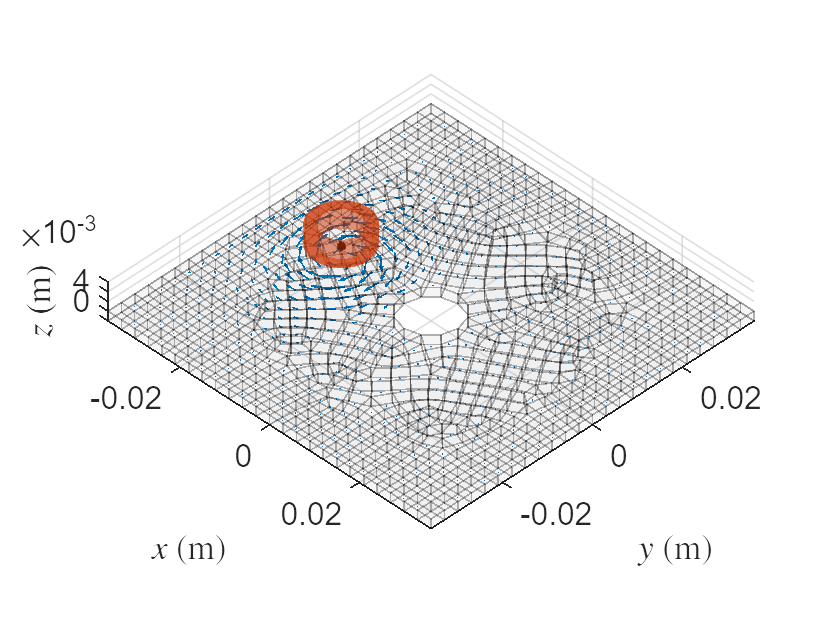

pos = Model.elms_center;
t = 0.3e-3; % (s)
[~,k] = min(abs(t - Model.time_domain.t));
vec = Model.time_domain.J(:,:,k);
quiver3(pos(1,:),pos(2,:),pos(3,:), vec(1,:),vec(2,:),vec(3,:));
clear t k pos vec

PlotWorld3D(Model, EM, Sensor);

clf

## Compare with FEA

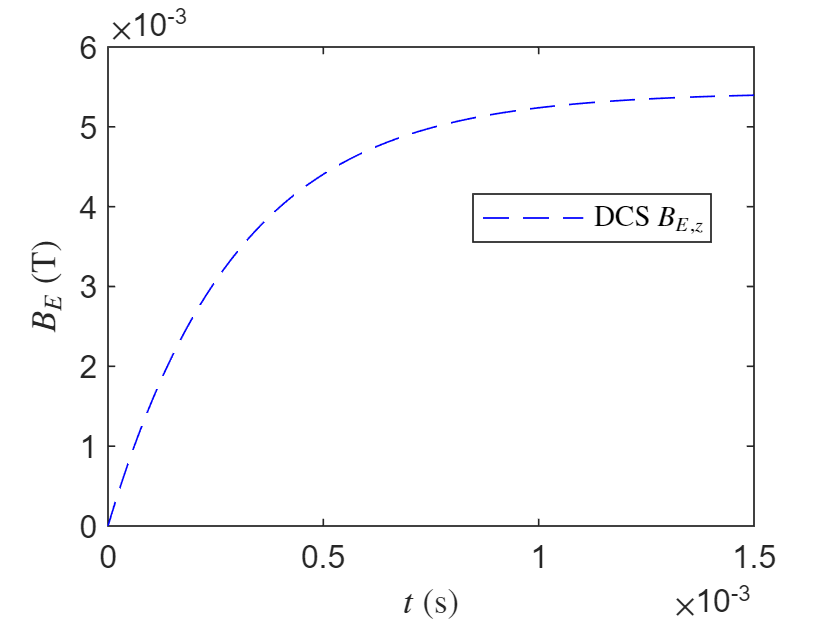

data = readmatrix('FEA_data/B_Ti.csv', 'CommentStyle','%');
data = reshape(data(4:end), 4, []);
FEA.t = data(1,:);
FEA.B_x = data(2,:);
FEA.B_y = data(3,:);
FEA.B_z = data(4,:);

% plot(FEA.t, FEA.B_C_z, 'c-', 'DisplayName','FEA $B_{E,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_E(3,1,:)), 'b--', 'DisplayName','DCS $B_{E,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')
hold off

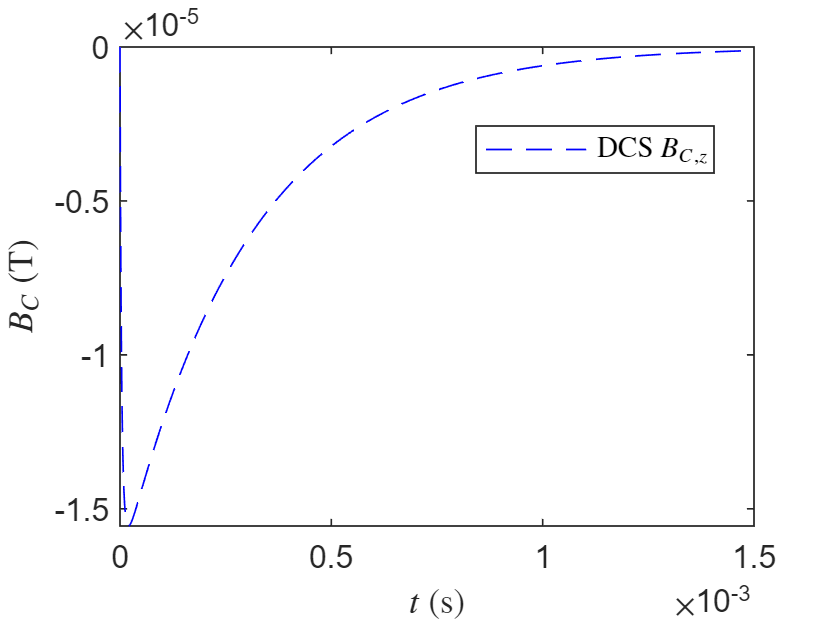

clf

% plot(FEA.t, FEA.B_z, 'c-', 'DisplayName','FEA $B_{C,z}$'); hold on
plot(Sensor.time_domain.t, squeeze(Sensor.time_domain.B_C(3,1,:)), 'b--', 'DisplayName','DCS $B_{C,z}$');
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$t$ (s)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')
hold off

clf

clear data